1.用来看相邻两张图片的影响（时间上的整体编码）

ori = struct();
co = struct();
for i = num
    fieldname = sprintf('session%d',i);
    ori.(fieldname) = floor((stimIDs_new.(fieldname)-1)/18)+1;
    ori.(fieldname)(73,:) = ori.(fieldname)(71,:);
    tar = find(mod(1:72,4)==0);
    sur1 = tar-1;
    sur2 = tar+1;
    surori = (ori.(fieldname)(sur1,:)+ori.(fieldname)(sur2,:))/2
    co.(fieldname) = ori.(fieldname)(tar,:)-surori;
    co.(fieldname)(19,:) = abs(mean(co.(fieldname)(1:18,:),1));
end

%cluster-label
for i = num 
    fieldname = sprintf('session%d',i);
    target = cluster.(fieldname).target1;
    blank = cluster.(fieldname).blank;
    random = cluster.(fieldname).random;
    co.(fieldname)(20,target) = ori.(fieldname)(4,target);
    co.(fieldname)(20,blank) = 0;
    co.(fieldname)(20,random) = -1;
end

2.汇总多天的数据

clear;
load('D:\Desktop\Ensemble coding\data\datanum.mat');
all_orientdata = {};
all_num = 4:12;
block = 'EC';
type = 0;
line = 4.5;
for i = 1:length(all_num)
    name = a{1,all_num(i)};
    time = a{2,all_num(i)};
    path = sprintf('D:\\Desktop\\Ensemble coding\\data\\%sdata',time);%数据存储路径
    %这个是用来数据种类的
    num = datanum.(sprintf('data%s',time)).(block);
    [timeseries, stimres, stimIDs] = load_matrix(num, name, path);
    [stimIDs_new] = real_sequence(num, stimres, stimIDs, type);
    % 分组为trb
    [cluster,cluster_data] = clusterdata(num, stimIDs_new, timeseries, type, name);
    ori = struct();
    co = struct();
    for ii = num
        fieldname = sprintf('session%d',ii);
        ori.(fieldname) = floor((stimIDs_new.(fieldname)-1)/18)+1;
        ori.(fieldname)(73,:) = ori.(fieldname)(71,:);
        tar = find(mod(1:72,4)==0);
        sur1 = tar-1;
        sur2 = tar+1;

        suror1 = abs(ori.(fieldname)(tar,:) - ori.(fieldname)(sur1,:));
        idx = suror1 > 9;
        suror11 = suror1;
        suror11(idx) = 18-suror1(idx);

        suror2 = abs(ori.(fieldname)(tar,:) - ori.(fieldname)(sur2,:));
        idx = suror2 > 9;
        suror21 = suror2;
        suror21(idx) = 18-suror2(idx);

        surori = (suror11+suror21)/2
        co.(fieldname) = surori;
        co.(fieldname)(19,:) = abs(mean(co.(fieldname)(1:18,:),1));
    end
    for ii = num
        fieldname = sprintf('session%d',ii);
        target = cluster.(fieldname).target1;
        blank = cluster.(fieldname).blank;
        random = cluster.(fieldname).random;
        co.(fieldname)(20,target) = ori.(fieldname)(4,target);
        co.(fieldname)(20,blank) = 0;
        co.(fieldname)(20,random) = -1;
    end
    trail_label.(sprintf('day%d',i)) = co;
    for orient = 1:2:17
        m = 1;
        all_orientdata{i,1,(orient+1)/2} = zeros(length(num),96,1021);
        all_orientdata{i,2,(orient+1)/2} = zeros(length(num),96,1021);
        for ii = num
            fieldname = sprintf('session%d',ii);
            ori_idx1 = find(co.(fieldname)(20,:)==orient & co.(fieldname)(19,:)<=line);
            ori_idx2 = find(co.(fieldname)(20,:)==orient & co.(fieldname)(19,:)>line);
            oridata1 = mean(timeseries.(fieldname)(ori_idx1,1:96,420:1440),1);
            oridata2 = mean(timeseries.(fieldname)(ori_idx2,1:96,420:1440),1);
            all_orientdata{i,1,(orient+1)/2}(m,:,:) = oridata1
            all_orientdata{i,2,(orient+1)/2}(m,:,:) = oridata2;
            m = m+1;
        end
    end
end

surori =     6.0000    6.5000    4.5000    4.5000    5.5000    3.0000         0    3.5000    2.5000    6.0000    2.5000    7.5000    3.5000    5.0000    6.5000    7.5000    5.0000    1.5000    2.5000         0    6.0000         0    5.5000    5.5000    5.5000    7.0000    4.5000    6.5000         0    5.5000    7.5000    6.0000         0    6.0000    7.0000    2.0000    5.5000    4.5000    3.5000    4.5000    6.5000    5.0000    8.0000    6.0000    8.0000    2.0000    6.0000    4.0000         0    4.0000
    7.5000    5.5000    5.5000    5.0000    5.5000    5.5000         0    5.0000    4.5000    7.0000    5.5000    7.0000    6.0000    4.5000    6.5000    2.0000    5.0000    6.5000    5.5000         0    1.5000         0    4.0000    7.0000    7.0000    3.0000    2.0000    3.0000         0    5.5000    4.5000    5.5000         0    3.0000    8.5000    4.0000    4.5000    6.5000    8.5000    7.0000    7.0000    5.0000    3.0000    6.0000    2.5000    5.0000    5.0000    7.0000         0

surori =     2.5000    3.5000    4.0000    5.5000    7.5000    3.5000    6.0000    4.5000    6.0000    3.5000    2.5000    6.0000    2.0000    4.5000    5.5000    6.5000         0    4.0000    2.5000    6.0000    2.5000    4.0000    5.0000    6.0000    4.5000         0    3.5000    5.0000    2.0000    6.5000    2.5000    8.5000    4.5000    4.5000         0    6.5000         0    3.5000    4.5000    3.5000    5.0000    5.5000    3.5000    3.0000    3.5000    3.5000    3.5000    4.0000    1.0000    6.5000
    3.0000    3.5000    3.0000    5.0000    6.5000    4.0000    4.5000    1.5000    5.0000    7.5000    5.0000    3.5000    7.0000    7.5000    6.0000    4.0000         0    2.5000    3.5000    5.5000    4.0000    4.5000    6.5000    5.0000    4.5000         0    6.0000    6.5000    6.5000    5.0000    5.0000    5.5000    1.5000    7.5000         0    5.5000         0    6.5000    5.5000    4.5000    6.5000    3.5000    2.0000    3.5000    4.5000    5.5000    7.0000    3.0000    2.0000

surori =     6.5000    4.5000    4.0000         0         0         0    3.5000    2.5000    4.0000    3.5000    4.5000    4.5000    4.5000    7.5000    6.0000    3.0000    0.5000    2.0000    4.0000    4.5000    7.5000    5.0000    6.5000    3.0000    2.5000    4.5000    8.0000    7.0000    6.0000    6.5000    5.5000    3.5000    6.5000         0    5.5000    5.0000    4.5000    7.0000    2.0000    5.0000         0    3.5000    8.0000         0    3.0000    3.5000    6.5000    4.5000    7.5000    8.0000
    2.0000    2.5000    8.0000         0         0         0    4.5000    4.5000    2.5000    6.5000    0.5000    3.5000    7.5000    7.0000    4.5000    6.0000    8.5000    2.5000    7.5000    4.5000    3.0000    6.5000    2.0000    5.0000    2.5000    8.5000    2.5000    4.5000    6.0000    5.5000    6.0000    6.5000    5.5000         0    1.5000    2.0000    7.5000    5.0000    5.0000    5.5000         0    5.5000    1.5000         0    4.5000    7.5000    6.5000    2.5000    4.0000

surori =     5.5000    2.5000    5.5000    4.5000    2.0000    4.5000    6.5000    5.0000    5.0000    3.5000    5.0000    7.5000    4.5000    7.0000    4.5000    2.5000    1.5000    4.0000    6.0000    6.5000         0         0    2.5000    7.0000    4.0000    4.0000    7.0000    4.5000         0    7.5000    6.5000    3.5000    5.0000    2.5000    3.5000    4.5000    4.5000    4.0000    4.5000         0    4.5000    6.5000    6.5000    4.0000    5.0000    3.5000    5.5000    6.5000         0         0
    6.5000    4.5000    2.0000    3.0000    1.5000    2.5000    6.0000    6.0000    7.0000    5.0000    7.5000    5.0000    8.0000    7.5000    2.5000    3.5000    1.5000    6.5000    5.5000    4.5000         0         0    2.5000    5.0000    7.0000    4.0000    5.0000    6.5000         0    3.5000    3.5000    5.5000    3.0000    3.0000    2.5000    6.0000    4.5000    5.5000    6.5000         0    6.0000    5.0000    3.0000    6.0000    2.5000    5.0000    5.0000    5.0000         0

surori =     1.5000    7.0000         0    3.0000    4.0000    5.0000    5.5000    3.5000    1.0000    5.5000         0         0    8.0000    3.5000    5.5000    5.0000    5.0000    6.0000    2.5000    4.0000    3.0000    7.5000    1.5000    5.5000    1.0000    5.0000    3.0000    3.0000    7.5000    5.0000    6.0000    8.0000    5.0000    3.0000    2.0000    2.5000    4.0000    6.5000    5.0000    7.0000    7.5000    2.5000    3.5000    6.5000    1.0000         0    7.5000    2.5000    3.0000         0
    5.0000    4.5000         0    5.0000    2.0000    5.0000    7.5000    4.5000    5.0000    2.0000         0         0    4.5000    5.5000    8.5000    5.0000    4.0000    2.5000    6.0000    4.0000    2.5000    2.5000    4.5000    5.5000    4.0000    7.5000    8.0000    7.0000    3.5000    3.0000    5.0000    4.5000    5.5000    4.0000    4.5000    7.0000    1.5000    5.0000    4.5000    5.0000    5.0000    6.0000    5.5000    5.5000    5.5000         0    4.0000    6.5000    7.5000

surori =     5.5000    4.5000    8.5000    5.0000    5.0000    5.5000    4.5000    4.5000    3.0000    5.0000    7.0000    5.5000    6.0000    6.0000         0    6.0000    3.5000    5.0000    1.0000    8.0000    4.0000    2.0000    4.5000         0    6.5000         0    5.5000    7.5000    3.0000    4.0000    3.0000    6.0000    5.5000    2.5000    5.5000    4.5000    4.5000    6.5000    5.0000    2.5000    5.5000    5.0000    5.0000    5.5000    7.5000    4.5000    4.5000    5.0000         0         0
    6.0000    5.5000    6.5000    5.5000    3.5000    8.5000    7.5000    1.5000    7.5000    6.0000    3.0000    4.0000    1.5000    6.0000         0    6.0000    3.0000    5.0000    2.5000    7.5000    1.0000    5.5000    4.5000         0    4.0000         0    4.5000    4.5000    6.0000    2.5000    6.0000    8.0000    5.5000    3.0000    5.0000    2.5000    3.5000    6.0000    2.5000    8.5000    5.5000    4.5000    8.5000    3.5000    4.5000    4.5000    2.5000    2.0000         0

surori =     3.5000    4.0000    4.0000    3.0000    3.0000    5.0000    3.5000    2.0000    3.0000         0    1.5000         0    6.5000         0    3.5000    6.0000    6.0000    6.0000    3.0000    7.0000    4.0000    4.0000    4.5000    5.5000    1.5000    6.0000    4.0000    5.5000    4.5000    2.5000    3.0000         0    4.5000    6.5000    4.5000    3.5000    1.5000    7.5000         0    5.5000         0    4.0000    5.5000    4.5000    5.5000    1.0000    3.0000    3.5000    3.0000    3.0000
    5.0000    8.0000    3.5000    5.5000    8.0000    5.0000    5.5000    5.0000    4.5000         0    3.5000         0    4.0000         0    6.5000    4.5000    5.0000    4.0000    6.5000    5.0000    4.0000    5.0000    1.5000    4.0000    2.0000    5.5000    2.0000    4.5000    5.5000    3.0000    7.5000         0    2.5000    5.0000    6.0000    3.0000    7.0000    4.5000         0    3.5000         0    8.5000    5.0000    3.0000    1.5000    4.0000    2.5000    4.0000    6.0000

surori =     3.5000    5.0000    5.0000    7.5000    2.5000    3.0000    6.0000    7.5000    6.0000    7.0000    5.0000    4.5000    3.0000         0    4.0000    5.0000    8.0000    4.0000         0    3.5000    2.5000    6.5000    5.5000    3.0000    3.0000    5.5000    7.5000    2.5000    2.0000    2.5000    4.5000    6.0000    1.5000         0    6.0000    2.5000         0    3.0000    5.5000    4.5000    2.0000    4.0000    5.0000    4.5000    7.0000    2.5000    6.0000    3.5000    6.5000    6.0000
    6.0000    7.0000    1.0000    6.0000    7.0000    3.5000    1.5000    4.0000    4.5000    3.5000    1.0000    8.0000    3.5000         0    3.5000    4.0000    1.0000    4.5000         0    3.5000    8.5000    4.0000    8.0000    2.0000    6.0000    6.0000    7.5000    3.0000    1.0000    4.5000    2.5000    6.5000    4.5000         0    6.0000    3.0000         0    6.5000    4.0000    5.0000    7.0000    5.0000    8.5000    4.0000    1.0000    2.0000    6.0000    5.0000    4.5000

all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2 cell 数组
    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×2 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×3 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×4 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×5 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×6 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×7 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×8 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata = 1×2×9 cell 数组
all_orientdata(:,:,1) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}


all_orientdata(:,:,9) = 

    {8×96×1021 double}    {8×96×1021 double}


surori =          0         0    3.5000    5.5000    6.5000    7.5000         0    3.5000    1.5000    5.5000         0    6.0000    4.0000    5.0000    5.5000    8.0000    6.0000    5.0000         0    8.0000    4.5000    5.0000    2.0000    5.5000         0    7.5000    4.5000    4.5000    5.5000    4.5000    3.0000    3.5000    6.0000    6.5000    5.0000    2.0000    2.5000    6.0000    6.0000    6.5000    7.0000    7.5000    3.0000    3.5000    6.0000    3.5000    5.5000    6.5000    2.5000    7.0000
         0         0    6.0000    6.5000    6.0000    2.0000         0    3.0000    6.5000    4.5000         0    1.5000    5.0000    5.5000    7.0000    3.0000    7.0000    4.5000         0    2.5000    5.5000    1.0000    5.0000    5.5000         0    2.0000    5.5000    5.0000    5.5000    5.5000    5.5000    5.0000    6.0000    3.0000    5.0000    2.0000    5.5000    5.0000    3.0000    5.5000    3.0000    7.0000    3.0000    9.0000    7.5000    8.5000    4.0000    7.0000    4.5000

surori =     2.0000    6.5000    3.5000         0    3.5000    4.0000    5.0000         0    3.5000    6.5000         0    4.5000    4.0000    3.5000    2.0000    4.0000    2.5000    2.5000    5.0000    4.0000    5.0000    6.0000         0    4.5000    7.5000    4.5000         0    3.5000    6.5000    4.5000    3.5000    4.5000    2.0000    5.5000         0    1.0000    2.5000    5.5000    4.5000    3.5000    4.5000    3.5000    4.0000    5.5000    4.5000    5.0000    4.5000    2.5000    6.5000    6.0000
    6.5000    5.0000    4.0000         0    5.5000    4.0000    3.5000         0    5.5000    5.5000         0    7.5000    3.0000    6.5000    7.5000    2.5000    3.5000    4.0000    6.5000    4.5000    6.5000    5.0000         0    4.5000    6.5000    6.5000         0    4.5000    4.0000    7.5000    7.5000    4.5000    7.0000    6.0000         0    2.0000    6.5000    5.5000    4.5000    6.0000    2.0000    3.5000    3.0000    4.5000    1.5000    4.0000    1.5000    5.0000    4.0000

surori =          0         0         0    2.5000    4.5000    4.5000    6.0000    3.0000    4.5000    2.0000    4.0000    4.5000         0    7.5000    7.5000    5.0000    6.5000    7.5000    4.5000    8.0000    3.5000    6.5000    5.5000    2.5000    4.5000    5.0000    7.5000    6.0000    4.5000    8.0000    7.0000    4.0000    4.0000    4.5000         0    3.5000    7.0000    8.0000    3.0000    3.0000    2.5000    6.5000         0    5.0000    6.5000    3.5000    5.0000    5.5000    7.5000    4.0000
         0         0         0    4.5000    3.5000    7.5000    4.5000    6.0000    2.5000    2.5000    7.5000    4.5000         0    3.0000    5.5000    6.5000    2.0000    7.0000    8.5000    2.5000    7.5000    5.5000    6.0000    5.0000    2.5000    4.5000    4.0000    5.0000    7.5000    6.0000    5.0000    4.5000    2.5000    0.5000         0    5.5000    6.0000    1.5000    4.5000    5.0000    2.5000    6.5000         0    2.0000    2.0000    4.5000    5.5000    4.5000    7.0000

surori =     5.5000    4.5000         0         0    7.0000    5.0000         0    5.0000    3.5000    4.5000    5.0000    7.5000    4.5000    6.5000    6.0000    4.0000    6.0000    6.5000         0    6.5000    2.5000    5.0000    5.0000    3.5000    5.5000    3.5000    7.0000    4.5000         0    5.0000    6.5000    2.5000    3.5000    6.5000    4.5000    5.5000    4.5000    2.0000    6.5000    1.5000    6.5000         0    3.0000    4.0000    4.0000    4.5000    7.5000    3.5000    5.0000    4.0000
    6.5000    6.5000         0         0    3.5000    6.0000         0    7.0000    5.0000    6.5000    7.5000    5.0000    8.0000    5.0000    7.5000    6.5000    5.5000    4.5000         0    5.0000    2.5000    2.5000    6.5000    5.0000    5.0000    6.0000    5.0000    6.5000         0    1.5000    3.5000    3.0000    2.5000    5.5000    6.0000    2.0000    3.0000    1.5000    6.0000    1.5000    3.0000         0    2.0000    7.0000    4.0000    5.5000    3.5000    5.5000    3.0000

surori =     6.5000    5.0000    5.5000    4.5000    3.0000    5.0000    7.0000    5.5000    6.0000         0    6.0000    4.5000    3.5000    5.0000    1.0000    4.0000    5.0000    4.0000    4.5000         0         0    5.5000    7.0000    7.5000    3.0000         0    5.5000    2.5000    4.5000    5.0000    5.5000         0    5.0000    5.0000    4.5000    5.5000    8.5000    5.0000    4.5000    6.0000    6.0000    2.0000    7.5000    3.0000         0    6.0000    4.5000    6.5000    2.5000    8.5000
    3.5000    5.5000    8.5000    1.5000    7.5000    6.0000    3.0000    3.5000    1.5000         0    6.0000    4.5000    3.0000    5.0000    2.5000    1.0000    2.0000    6.0000    4.5000         0         0    4.5000    6.0000    7.0000    6.0000         0    5.5000    3.0000    3.5000    2.5000    5.5000         0    4.5000    8.5000    3.5000    6.0000    6.5000    3.5000    7.5000    6.0000    1.5000    5.5000    4.5000    6.0000         0    8.0000    2.5000    6.0000    8.5000

surori =     4.5000    5.5000    5.0000    5.5000    4.5000    5.0000    5.5000    6.5000    4.5000    4.5000    1.0000    4.0000    5.0000    6.0000    4.5000         0         0    7.5000    7.0000    3.0000    3.0000         0    6.0000    4.5000    6.5000    2.5000    4.5000    8.5000         0    6.0000    2.0000    4.5000    8.5000    5.5000         0    3.5000    8.0000    6.0000    4.0000    6.5000         0    4.0000    2.5000    2.5000    5.0000    6.5000    5.0000    3.0000    6.0000    5.0000
    3.5000    6.0000    5.5000    8.5000    7.5000    6.0000    3.5000    5.0000    4.5000    2.5000    2.5000    1.0000    2.0000    1.5000    4.5000         0         0    4.5000    6.0000    6.0000    6.0000         0    8.0000    3.5000    6.0000    8.5000    7.0000    1.5000         0    6.5000    7.0000    5.5000    6.5000    4.0000         0    3.0000    7.5000    7.0000    6.0000    4.0000         0    2.5000    3.0000    5.5000    5.0000    3.5000    3.5000    7.5000    6.0000

surori =          0    4.0000    4.0000    4.5000    5.5000    3.5000         0    1.5000         0         0    6.0000    6.0000    3.0000    4.0000    5.5000    1.5000    5.5000    6.0000    5.5000    4.5000    3.0000         0    5.5000    1.0000    4.5000    3.5000    1.5000    7.5000    5.0000         0    4.5000    5.5000    3.0000    5.0000    1.0000    3.0000    3.0000    2.0000    3.5000    3.5000    3.0000    3.0000    4.0000    6.5000    4.0000    2.5000    4.5000    6.5000    8.0000    4.5000
         0    8.0000    3.5000    3.0000    1.5000    5.5000         0    3.5000         0         0    4.5000    4.0000    6.5000    5.0000    4.0000    2.0000    5.5000    5.5000    4.5000    5.5000    7.5000         0    1.5000    6.0000    4.5000    3.0000    7.0000    4.5000    8.0000         0    2.0000    5.0000    5.5000    5.0000    4.0000    4.5000    2.5000    5.0000    6.5000    4.0000    6.0000    2.5000    4.0000    4.5000    2.0000    3.0000    2.5000    5.0000    3.0000

surori =     5.5000         0    3.5000    5.0000    7.5000    3.0000    5.0000    4.5000    2.5000    7.0000    6.0000    3.0000         0    5.0000    8.0000    3.5000    4.5000         0    3.5000    2.5000    7.0000    6.5000    5.5000    2.5000    3.0000    5.5000    2.5000    2.5000    1.5000    4.0000         0    6.0000    6.0000    8.5000    2.5000         0    2.0000    3.5000    4.0000    6.0000    6.0000    7.0000    5.0000    4.5000    4.0000    4.0000    3.0000    3.5000    6.5000    4.5000
    6.0000         0    4.0000    1.0000    6.0000    3.5000    8.5000    4.0000    2.0000    3.5000    6.0000    3.5000         0    4.0000    1.0000    4.5000    3.5000         0    3.5000    8.5000    3.0000    4.0000    8.0000    5.0000    6.0000    6.0000    3.0000    4.5000    4.5000    7.0000         0    5.0000    6.0000    5.0000    3.0000         0    7.0000    6.0000    5.0000    1.5000    4.5000    1.0000    1.0000    8.0000    3.5000    4.5000    7.0000    5.0000    4.5000

surori =     3.5000    4.5000    6.5000         0         0    6.5000    5.0000    5.0000    6.0000    5.0000    2.0000    4.5000    2.5000    3.5000    7.0000    5.0000    6.5000    6.0000    8.0000    2.5000    6.5000    4.5000    2.5000    4.5000         0    6.5000         0    6.5000    2.5000    3.5000    4.0000    3.0000    1.5000    7.5000    6.5000    4.5000    7.0000    5.5000    6.5000    3.0000    2.5000    7.5000    3.5000    4.0000    6.5000    2.0000    6.0000    5.0000    3.5000    2.0000
    3.5000    4.5000    5.5000         0         0    3.0000    3.0000    3.5000    4.0000    1.5000    4.0000    3.5000    8.0000    4.0000    6.5000    7.0000    8.0000    7.0000    3.0000    8.5000    5.5000    3.5000    5.0000    5.5000         0    3.0000         0    4.0000    2.0000    6.5000    6.5000    1.5000    6.0000    8.5000    4.5000    5.0000    4.5000    5.0000    4.0000    1.5000    7.0000    2.5000    4.0000    2.5000    6.0000    6.0000    3.5000    1.5000    7.0000

surori =     3.0000    3.0000    1.5000    4.5000    3.5000    5.0000    4.0000         0    4.0000    4.0000    4.5000    3.0000    6.0000    3.5000    7.5000    3.5000    3.5000    7.0000    6.0000    4.5000    4.5000    5.5000    5.5000    5.0000         0    2.0000    5.0000    6.5000    2.5000    5.5000    4.5000    5.0000    1.0000    3.0000    5.0000    8.0000    5.0000    3.5000    2.5000    5.0000    5.0000    2.5000    7.0000    6.5000    5.5000         0    8.5000    5.5000    5.5000    2.5000
    4.5000    8.5000    3.0000    5.0000    4.5000    7.0000    4.5000         0    4.5000    7.5000    5.5000    5.5000    6.0000    7.0000    5.5000    5.0000    2.5000    4.0000    5.0000    6.0000    2.5000    4.0000    7.0000    4.0000         0    6.5000    4.5000    7.0000    3.0000    1.5000    6.5000    3.5000    5.5000    5.0000    5.0000    6.0000    3.5000    5.0000    2.0000    5.5000    2.5000    4.5000    3.5000    6.0000    8.0000         0    3.5000    3.0000    4.5000

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,9)

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdat

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orien

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_o

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}


a

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    {8×96×1021 double}    {8×96×1021 double}
    {0×0       double}    {0×0       double}

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

all_orientdata = 2×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,7) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,8) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 dou

surori =          0    4.0000    7.5000    5.5000    4.5000    4.5000    5.5000    6.0000    5.5000         0    3.5000    4.5000    2.0000    8.0000    4.0000    6.0000         0    2.0000    8.5000    3.0000    5.0000    6.0000         0         0    2.0000    3.5000         0    6.0000    2.0000    4.0000    4.0000    3.0000    3.5000    2.5000    5.5000    6.0000    6.0000    1.5000    8.0000    5.0000    3.5000    4.5000    7.0000    7.5000    5.5000    4.0000    2.5000    7.5000    6.5000    5.0000
         0    3.0000    4.5000    6.0000    7.5000    4.0000    6.5000    1.5000    6.5000         0    3.5000    5.0000    5.5000    4.0000    5.5000    7.0000         0    6.0000    5.0000    3.5000    4.0000    2.5000         0         0    4.5000    6.0000         0    5.0000    4.0000    2.5000    5.0000    7.0000    6.0000    3.5000    7.0000    9.0000    2.5000    6.0000    3.5000    6.0000    4.0000    2.5000    6.0000    5.0000    3.0000    2.0000    2.0000    5.5000    4.5000

surori =     3.5000         0         0    7.5000    3.5000    4.5000         0    3.5000         0    5.5000         0         0    7.0000    2.0000    8.5000    6.0000    3.5000    4.0000    2.5000    4.0000    4.0000    8.0000    5.0000    1.0000    6.0000    3.5000    2.5000    5.0000    5.5000    6.0000    5.5000    5.0000    5.5000    4.5000    8.0000    1.5000    1.5000    3.0000    4.5000    3.0000    5.5000    6.5000    8.5000    4.0000    6.5000    5.5000    6.0000    4.0000    7.5000    4.0000
    6.0000         0         0    4.5000    4.5000    6.5000         0    4.0000         0    6.5000         0         0    4.5000    4.5000    6.0000    4.0000    3.5000    2.0000    2.0000    2.5000    5.5000    3.5000    6.0000    7.0000    1.5000    6.0000    3.5000    4.0000    7.0000    9.0000    3.0000    5.5000    6.0000    7.5000    4.0000    6.0000    4.0000    7.0000    3.5000    4.5000    6.5000    4.5000    5.0000    3.0000    6.0000    6.0000    2.5000    3.0000    5.5000

surori =     2.5000    5.0000    3.5000    3.0000    5.5000    5.5000    2.0000    6.5000         0         0    3.5000    8.5000    4.0000         0    2.5000    6.5000    3.5000         0    5.5000    3.5000    6.5000    2.0000    4.0000    2.5000    1.0000    2.5000    5.0000    4.0000         0    7.0000    4.5000    4.0000    2.5000    4.5000    6.0000    4.5000    5.0000    5.0000    3.5000    4.0000         0    2.5000    5.5000    5.5000    6.0000    7.5000    4.5000    6.5000    5.0000    3.5000
    3.0000    6.5000    3.5000    3.5000    5.0000    4.5000    6.5000    5.0000         0         0    5.5000    5.5000    4.0000         0    5.0000    5.5000    7.0000         0    6.0000    6.5000    4.0000    7.5000    2.5000    3.5000    2.0000    4.0000    6.5000    4.5000         0    2.5000    2.0000    3.0000    5.0000    1.5000    4.5000    7.5000    3.5000    3.5000    7.5000    3.0000         0    6.5000    5.5000    3.5000    5.0000    6.5000    6.5000    4.0000    4.0000

surori =     5.5000    6.5000    4.5000    4.5000    5.0000    5.0000    6.0000    8.5000    5.5000         0    5.0000    1.5000    6.0000    6.0000    7.5000    3.5000    5.5000    4.0000    8.0000    7.0000    5.5000    2.0000    2.5000    7.0000    7.5000    5.0000    4.5000         0    5.0000    5.5000         0         0         0    6.0000    7.0000    6.5000    1.5000         0    3.5000    5.0000    5.5000    2.0000    6.0000    5.5000    7.5000    3.5000    8.5000    5.0000    4.5000    6.0000
    5.0000    5.0000    5.0000    2.5000    1.0000    6.0000    5.0000    2.0000    5.5000         0    5.5000    6.5000    5.0000    1.5000    4.5000    5.0000    3.5000    5.0000    4.0000    4.5000    4.0000    4.5000    2.0000    5.5000    2.5000    2.5000    1.5000         0    4.0000    3.5000         0         0         0    7.5000    6.0000    3.5000    4.5000         0    5.0000    8.0000    6.5000    2.5000    6.5000    3.0000    7.0000    1.5000    8.0000    3.0000    3.0000

surori =     4.0000    3.0000    6.0000    3.5000    4.5000    7.0000         0         0    6.5000    3.5000    5.0000    5.0000    6.0000    5.0000    4.5000    7.0000    4.5000    6.5000         0    2.5000    2.5000    3.5000    3.5000    6.5000    8.0000    6.5000    5.5000    2.5000         0    5.0000    3.5000         0    3.5000    6.5000    6.5000    1.5000    3.5000    7.0000    6.0000    5.0000    2.0000    4.5000    4.5000         0    2.5000    7.0000    2.0000    6.0000    3.0000    5.5000
    6.5000    1.5000    2.5000    3.5000    4.5000    4.0000         0         0    3.0000    4.0000    3.0000    3.5000    4.0000    1.5000    5.0000    4.5000    3.5000    4.0000         0    8.0000    7.0000    4.5000    4.0000    8.0000    3.0000    5.5000    4.0000    5.0000         0    1.5000    7.0000         0    3.5000    5.5000    5.5000    6.0000    4.0000    6.5000    7.0000    6.5000    6.0000    3.5000    5.5000         0    2.0000    3.5000    4.0000    6.5000    1.5000

surori =     4.5000         0         0         0    5.0000    3.5000    4.5000    5.5000    3.5000    7.0000    4.0000    4.0000    8.0000    4.5000    7.5000    3.0000    6.5000    4.5000    7.0000    4.0000    5.5000    3.5000    2.5000         0    4.5000    7.5000    6.0000    4.5000    8.0000    4.0000         0    0.5000    4.5000    6.5000         0    7.5000    5.0000    7.5000    2.5000    8.0000    6.5000    6.5000    5.0000    6.5000    3.5000    2.5000    4.5000    6.0000    2.0000    6.5000
    2.5000         0         0         0    5.5000    6.5000    0.5000    4.5000    5.5000    6.0000    3.5000    7.5000    1.5000    4.5000    5.5000    5.0000    2.0000    8.5000    4.5000    7.0000    6.0000    6.5000    5.0000         0    2.5000    4.0000    5.0000    7.5000    6.0000    4.5000         0    8.5000    2.5000    3.5000         0    3.0000    6.5000    7.0000    2.5000    2.5000    6.5000    5.5000    4.5000    2.0000    4.5000    4.5000    3.5000    4.5000    2.5000

surori =     7.0000    6.0000    4.5000    6.5000         0    3.5000    7.5000    5.0000    4.5000    7.0000    5.5000    6.0000    3.0000         0    7.5000    5.5000    5.0000    4.5000    5.5000    8.0000    5.0000    2.5000    6.5000    5.5000    6.0000    2.5000         0    2.5000    4.0000    3.5000    7.0000    6.5000    5.0000    6.5000    6.5000    3.5000    3.5000    6.5000    3.0000         0    1.5000    2.0000    4.5000    2.5000    7.0000    6.5000    3.5000    3.5000         0    2.5000
    3.5000    2.5000    4.5000    5.5000         0    4.0000    8.5000    1.5000    5.0000    4.5000    5.0000    6.5000    1.5000         0    2.5000    5.0000    7.0000    3.5000    4.5000    3.0000    6.5000    8.5000    5.5000    4.0000    3.5000    5.0000         0    2.0000    6.5000    3.5000    4.0000    5.5000    3.5000    4.5000    4.0000    4.5000    4.0000    8.0000    1.5000         0    6.0000    4.0000    3.5000    8.0000    6.5000    6.0000    7.0000    3.5000         0

surori =     4.5000    5.5000         0    3.5000    2.5000    3.0000    7.5000    4.5000    7.0000    5.0000         0    5.0000    8.0000    4.5000         0    3.5000    3.5000    7.0000    5.5000    6.5000    2.0000    2.5000    6.0000         0    2.5000         0    2.0000    3.5000    5.0000    4.0000    5.0000    6.0000    3.0000    5.0000    7.0000    4.0000    2.5000    3.0000    7.5000    4.0000    6.0000    8.5000    6.0000    3.0000    7.5000    4.5000    4.0000    6.5000    2.5000    1.5000
    5.0000    6.0000         0    6.0000    7.0000    3.5000    4.0000    4.0000    3.5000    1.0000         0    4.0000    1.0000    3.5000         0    5.0000    3.5000    3.0000    8.0000    4.5000    1.0000    4.5000    6.5000         0    3.0000         0    7.0000    4.0000    1.0000    5.0000    8.5000    6.0000    3.5000    7.5000    3.5000    4.5000    8.5000    6.0000    7.5000    7.0000    6.0000    5.0000    3.5000    6.5000    6.0000    8.0000    3.5000    4.0000    3.0000

surori =          0    4.0000    4.5000    3.5000    4.0000    4.0000    3.0000    5.5000         0         0         0    6.0000    1.5000    6.5000         0    6.5000    4.5000    4.5000    1.5000    7.5000    5.0000         0    4.5000    3.0000    3.0000    1.5000    2.0000    3.5000    3.5000    6.0000    3.0000    7.0000    4.0000    4.0000    4.5000    4.0000    5.5000    3.0000    5.5000    4.5000    3.0000    5.5000    3.5000    3.0000    3.0000    3.0000    5.5000    6.0000    2.5000    4.0000
         0    8.5000    5.0000    5.0000    8.0000    3.5000    8.0000    1.5000         0         0         0    4.0000    2.0000    4.5000         0    5.0000    4.0000    4.5000    7.0000    4.5000    8.0000         0    3.0000    5.5000    4.5000    3.5000    5.0000    6.5000    4.0000    4.5000    6.5000    5.0000    4.0000    5.0000    1.5000    2.0000    4.5000    7.5000    3.5000    2.0000    4.5000    5.0000    5.5000    2.5000    6.0000    2.5000    5.5000    5.5000    3.0000

surori =     6.5000    5.5000    4.5000    8.5000    4.5000    5.5000    6.0000    7.5000    6.5000         0    4.5000    5.0000    8.0000    5.0000    4.0000    6.0000    2.0000         0    6.5000    7.0000    3.0000    4.0000         0    5.5000    4.5000    6.5000    2.5000    5.0000    5.5000         0    5.0000    5.0000    4.5000    5.5000    4.5000    5.0000    7.0000    6.0000    6.0000    4.5000    1.0000    6.0000         0    7.5000         0    7.5000    3.0000    2.5000    2.0000    4.5000
    3.5000    6.0000    5.5000    6.5000    7.5000    4.0000    1.5000    4.5000    5.0000         0    4.5000    5.0000    7.5000    2.0000    6.0000    1.5000    5.5000         0    4.0000    6.0000    6.0000    2.5000         0    5.5000    3.5000    6.0000    5.5000    2.5000    5.5000         0    5.0000    8.5000    3.5000    8.5000    1.5000    6.0000    3.0000    6.0000    6.0000    2.5000    2.5000    7.0000         0    4.5000         0    7.0000    6.0000    3.0000    2.0000

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

all_orientdata = 3×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,6) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    

surori =     4.0000    2.0000         0    6.0000         0    4.0000    4.5000    5.5000    5.5000    4.5000    3.0000         0    7.0000    5.0000    2.5000    7.0000    5.0000         0    8.0000    4.5000    5.0000    6.5000    4.0000    6.5000    6.0000         0    5.0000    7.0000    5.5000    3.5000    4.5000    4.5000    3.5000    5.5000    5.0000    5.5000    3.5000    6.0000    7.5000    5.5000    6.0000    7.5000         0    1.5000    3.0000    4.0000    2.5000    6.0000    8.5000    2.5000
    2.5000    4.0000         0    7.5000         0    5.0000    5.0000    4.0000    7.0000    7.0000    5.5000         0    3.0000    5.0000    4.5000    8.0000    4.5000         0    2.5000    5.5000    1.0000    6.5000    7.0000    6.0000    5.5000         0    5.0000    7.0000    4.5000    9.0000    6.5000    5.5000    8.5000    5.5000    5.5000    7.0000    5.0000    7.0000    7.0000    5.5000    5.0000    4.5000         0    6.5000    3.0000    2.5000    5.5000    1.5000    6.5000

surori =     4.5000         0    2.0000         0         0    3.5000    4.0000    5.0000    4.0000         0    4.5000    3.5000    7.5000    3.0000    0.5000    4.5000    4.0000    4.0000    4.5000    6.5000         0    7.5000    7.5000    6.5000    5.5000    7.5000    6.5000    7.0000    6.5000    5.5000         0    6.5000    7.5000    8.0000    2.5000    4.5000    4.5000    5.0000    3.0000    2.5000    8.0000    3.5000    4.0000    6.0000    5.5000    7.0000    4.0000    3.5000    8.0000    3.5000
    2.5000         0    5.0000         0         0    4.5000    4.5000    5.5000    2.5000         0    7.5000    5.5000    7.0000    6.0000    8.5000    2.5000    3.5000    7.5000    4.5000    3.5000         0    3.0000    5.5000    2.0000    6.5000    7.0000    2.0000    4.5000    6.5000    6.0000         0    4.5000    4.0000    6.0000    4.5000    0.5000    3.5000    6.5000    5.0000    2.5000    2.5000    7.5000    7.0000    6.0000    1.5000    5.0000    8.0000    6.5000    1.5000

surori =          0    3.0000    5.5000    3.5000    3.0000    5.5000    4.5000    5.5000    2.5000    3.5000    5.0000    4.0000         0    4.0000    3.5000    3.5000    6.0000    4.5000    5.5000    5.0000         0    4.0000         0    5.5000    4.5000    5.0000    2.0000    1.0000    3.0000    5.0000         0    8.0000    5.0000    6.0000    3.5000    5.0000    5.0000    7.0000    6.5000    4.0000    4.0000    4.5000    3.0000    6.0000    3.5000    7.0000    5.5000    5.0000    6.5000    2.0000
         0    4.5000    1.5000    4.5000    8.5000    4.5000    5.0000    4.5000    3.0000    4.5000    7.0000    4.5000         0    4.5000    7.0000    2.5000    5.0000    6.0000    4.0000    4.0000         0    5.5000         0    1.5000    6.5000    3.5000    5.5000    5.5000    5.0000    5.0000         0    6.0000    3.5000    5.0000    5.0000    5.5000    2.5000    3.5000    6.0000    8.0000    7.5000    5.5000    5.5000    6.0000    5.0000    4.0000    7.0000    4.5000    7.0000

surori =     6.5000    5.5000    5.5000    4.0000    3.0000    6.5000    6.0000    5.0000    3.5000         0    6.5000    1.5000    5.0000    6.5000    7.0000    4.0000    0.5000    6.5000         0         0    5.5000    6.0000    4.5000    4.0000    4.0000    4.5000    7.0000         0    4.0000    5.0000         0    7.0000    6.5000    7.0000    2.5000    1.5000    5.5000    6.5000    3.5000    6.0000    1.0000         0    7.0000    4.0000    4.5000    3.0000    4.0000    6.5000    4.0000    6.5000
    6.0000    3.0000    4.5000    2.5000    5.5000    5.0000    5.0000    7.0000    5.5000         0    4.5000    7.0000    5.5000    2.5000    5.0000    2.5000    3.0000    5.0000         0         0    3.0000    5.0000    5.0000    3.0000    5.0000    4.0000    1.5000         0    6.5000    1.0000         0    7.5000    3.5000    3.5000    6.0000    5.0000    6.0000    8.0000    7.0000    6.5000    3.5000         0    4.0000    7.0000    4.0000    5.0000    4.0000    5.5000    5.0000

surori =     3.5000         0    3.5000         0    7.5000    3.5000    4.5000    5.0000    5.5000    4.5000    2.0000    4.5000    1.5000    4.0000    4.5000    6.0000         0    3.0000    4.5000    5.0000    3.5000    1.0000    6.0000    3.5000    2.5000    8.5000    3.0000    4.0000    3.0000    5.5000    6.0000    6.5000    5.0000         0    5.5000         0    7.0000    5.5000    2.0000    8.5000    6.0000    6.0000    4.0000    2.0000    8.0000    2.5000    4.0000    4.5000    6.5000    5.0000
    6.0000         0    3.5000         0    4.5000    4.5000    5.0000    5.5000    6.0000    7.5000    5.5000    6.5000    6.0000    5.0000    3.5000    7.0000         0    4.5000    4.0000    6.0000    4.0000    7.0000    1.5000    6.0000    3.5000    5.0000    3.5000    3.0000    3.5000    7.0000    2.5000    6.0000    4.0000         0    6.5000         0    4.5000    3.0000    4.5000    6.0000    4.0000    5.0000    2.0000    4.0000    4.0000    2.5000    5.5000    2.5000    4.5000

surori =          0    5.0000    2.0000    4.0000         0    7.0000    3.5000    2.5000    3.5000    8.0000    4.5000         0    4.0000    4.5000    3.0000    7.0000    3.0000    4.0000    7.0000    3.0000    5.0000    8.5000    8.0000    4.0000    4.5000         0         0    5.0000    6.0000    7.0000    3.5000    5.0000    1.5000    3.5000    5.5000         0    7.5000    2.5000    6.5000    6.0000    5.0000    6.5000    3.0000    5.5000    6.0000    5.0000    3.5000    4.0000    6.0000    3.5000
         0    4.5000    3.0000    8.0000         0    4.0000    5.0000    5.5000    7.0000    5.0000    4.5000         0    5.0000    3.0000    3.5000    2.0000    3.0000    2.5000    1.5000    5.0000    5.0000    4.5000    2.5000    1.5000    4.0000         0         0    1.5000    5.5000    4.5000    2.0000    8.0000    5.0000    6.5000    4.5000         0    5.0000    6.0000    6.5000    6.5000    2.0000    5.0000    2.5000    4.5000    5.0000    7.5000    3.5000    7.0000    1.5000

surori =          0    3.0000    4.0000    3.5000    5.5000    4.0000    4.0000    4.5000    3.0000    1.0000         0    3.0000         0    3.5000    6.0000    6.0000    6.0000    3.0000    3.0000    7.0000    3.0000    5.5000    1.5000    6.5000    5.5000    4.5000    2.5000    4.0000         0    4.5000    6.5000    4.5000    1.0000    5.0000    4.5000    3.0000    5.0000    2.0000    1.5000    6.5000    5.5000    6.0000    3.0000    4.5000    3.5000    5.0000         0    4.5000    8.0000    5.5000
         0    4.5000    8.5000    5.0000    5.0000    8.0000    3.5000    3.0000    8.0000    4.0000         0    2.5000         0    4.0000    4.5000    5.0000    4.0000    6.5000    6.0000    5.0000    2.5000    4.0000    2.0000    4.5000    4.5000    5.5000    3.0000    6.5000         0    2.5000    5.0000    6.0000    6.0000    8.0000    5.0000    5.5000    5.0000    5.0000    3.5000    4.0000    5.5000    5.5000    7.5000    4.5000    3.0000    6.5000         0    2.0000    4.5000

surori =     3.0000    7.0000    6.0000    3.5000    4.5000    6.5000    7.0000         0         0    6.5000    1.5000    3.5000    5.0000    5.0000    4.5000    5.5000    6.5000         0    8.5000    2.5000    7.5000    5.5000    7.0000    3.5000    4.0000    5.0000    6.5000    5.5000    6.5000    6.5000    2.0000    5.5000    6.0000    2.5000    4.5000         0    2.0000    3.5000         0    6.5000    3.5000    4.0000    6.5000    5.0000    6.0000    7.5000    6.5000    2.0000    7.0000    4.5000
    1.5000    3.5000    2.5000    3.5000    4.5000    5.5000    4.0000         0         0    3.0000    6.0000    4.0000    3.0000    1.5000    5.0000    5.0000    4.0000         0    7.0000    8.0000    2.5000    5.0000    6.5000    4.5000    2.5000    7.0000    8.0000    4.5000    6.0000    5.5000    6.0000    4.0000    3.5000    5.0000    5.5000         0    7.5000    3.5000         0    4.0000    6.5000    6.5000    5.5000    3.5000    4.0000    8.5000    4.5000    4.0000    4.5000

surori =          0    4.5000    5.5000    4.0000    4.5000    8.0000    3.0000    5.5000    3.5000    2.0000         0    1.5000         0    3.5000    6.0000    3.0000    3.0000    7.0000    3.0000    4.0000    5.5000    6.5000    4.5000    3.0000         0    5.0000    6.5000    5.5000    4.5000    3.5000    5.0000         0    4.5000    4.0000    3.5000    5.0000    1.0000    3.0000         0    2.0000    6.0000    4.0000    4.5000    5.5000    6.0000    5.5000    4.5000    5.0000    7.5000    5.5000
         0    5.0000    5.0000    3.5000    3.0000    4.5000    8.0000    1.5000    5.5000    5.0000         0    3.5000         0    6.5000    5.0000    6.5000    6.0000    5.0000    2.5000    4.0000    4.0000    4.5000    5.5000    7.5000         0    4.0000    5.0000    1.5000    4.0000    3.0000    8.0000         0    2.0000    8.5000    5.0000    5.0000    4.0000    4.5000         0    5.0000    4.5000    5.0000    1.5000    5.5000    5.5000    4.5000    4.5000    6.5000    4.5000

surori =     1.5000    4.0000    8.0000         0    4.0000    3.0000    2.5000    3.0000    2.0000         0    2.5000    5.5000         0    5.0000    5.0000    2.0000    5.0000    7.0000    5.0000    6.0000    4.5000    4.0000    7.5000    3.0000    7.5000    2.5000    5.5000    3.0000    3.5000    6.5000    4.5000    3.0000    1.0000    3.0000         0         0    6.0000    7.0000    2.5000    5.0000    5.0000    5.5000    1.0000    3.5000    4.0000    7.0000         0    3.5000    2.5000    1.0000
    5.0000    5.0000    4.5000         0    2.0000    7.5000    1.5000    4.0000    4.5000         0    7.0000    2.0000         0    5.0000    4.5000    0.5000    5.0000    5.0000    4.0000    2.5000    1.5000    4.0000    5.0000    2.5000    2.5000    6.0000    5.5000    3.5000    5.5000    5.5000    6.0000    8.0000    5.5000    7.0000         0         0    5.0000    4.5000    6.5000    5.5000    5.0000    7.5000    5.0000    7.5000    1.5000    2.5000         0    5.5000    6.0000

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

all_orientdata = 4×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}


all_orientdata(:,:,5) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×9

surori =          0         0    3.0000         0         0    2.0000    3.5000    3.0000    3.0000    4.5000    4.5000    2.5000         0    4.5000    8.0000         0    4.5000    3.0000    6.0000    3.0000    4.0000    6.5000    6.5000    4.5000    3.5000    4.0000    4.0000    3.0000    1.0000    6.0000    6.0000    4.0000    5.5000    6.0000    4.0000    5.0000    4.5000    1.5000    5.5000    3.5000    2.0000    1.5000    6.5000    1.5000    5.0000    4.5000    3.0000    4.0000    3.0000    3.5000
         0         0    2.5000         0         0    5.0000    6.5000    6.5000    2.5000    1.5000    5.5000    3.0000         0    2.5000    3.0000         0    5.0000    5.5000    4.5000    6.0000    4.0000    4.5000    5.0000    4.5000    3.0000    8.5000    3.5000    8.0000    4.0000    5.0000    4.0000    5.0000    5.5000    5.5000    2.0000    4.0000    6.0000    7.0000    1.5000    5.5000    5.0000    3.5000    4.0000    2.0000    6.5000    2.0000    4.5000    8.0000    4.5000

surori =          0    4.5000    4.0000    3.0000    5.0000         0    3.0000         0    2.0000    3.5000    3.5000    6.0000    3.0000    3.0000    4.0000    4.5000    1.5000    6.5000    4.0000    4.5000         0    6.5000    5.5000    8.0000    4.5000    4.5000    1.0000    7.5000         0    5.5000    4.0000    5.5000    4.0000    4.5000    3.5000    2.0000    1.0000    6.5000         0    3.0000    7.0000    4.0000    5.5000    5.5000    2.5000    4.5000    5.0000    1.5000    5.0000    3.0000
         0    5.0000    8.0000    8.0000    5.0000         0    2.5000         0    5.0000    6.5000    4.0000    5.0000    6.0000    2.5000    5.0000    1.5000    2.0000    4.5000    2.0000    5.5000         0    5.0000    1.5000    3.0000    4.0000    6.0000    6.0000    4.5000         0    3.5000    8.5000    5.0000    3.5000    3.0000    5.5000    5.0000    4.0000    4.0000         0    6.5000    5.0000    4.0000    4.0000    4.5000    3.0000    2.5000    4.0000    7.0000    8.0000

surori =     7.0000    2.5000    3.5000    5.0000    3.5000    4.0000    5.5000    7.5000    2.0000         0    3.5000         0    3.5000    5.0000    6.0000    4.0000    5.0000         0    6.0000    5.0000    3.5000    2.5000    6.5000    4.5000         0    4.5000    4.0000    3.5000    2.0000         0    1.0000    6.0000    3.5000    5.5000    5.5000    6.5000    3.5000    8.5000    4.5000    3.5000    4.5000    2.5000    2.5000    2.5000    5.5000    6.0000    4.5000         0    4.5000    2.5000
    2.5000    3.0000    6.0000    6.5000    3.5000    3.0000    5.0000    6.5000    6.5000         0    4.0000         0    5.5000    4.0000    4.5000    4.0000    3.5000         0    5.0000    3.5000    5.5000    5.0000    5.5000    4.5000         0    7.5000    3.0000    6.5000    7.5000         0    2.0000    5.5000    4.5000    3.5000    4.5000    5.0000    4.5000    5.5000    1.5000    7.0000    5.5000    3.5000    4.0000    6.5000    5.5000    5.0000    4.5000         0    6.5000

surori =     4.5000         0         0         0    3.5000    4.0000    5.0000    4.0000    4.5000    3.5000    6.0000    0.5000    7.0000    4.0000    4.5000    5.5000    2.5000    4.5000    8.0000    7.0000    6.5000         0    4.5000    6.5000    7.5000    5.0000    7.0000    2.0000         0    7.5000    4.5000    7.5000    3.0000    7.5000    6.5000    4.0000    6.0000    6.0000    4.5000    6.5000    2.5000    8.0000    6.5000         0    3.5000    6.5000    5.5000    3.5000    2.5000    5.5000
    2.5000         0         0         0    4.5000    4.5000    5.5000    2.5000    7.5000    5.5000    4.5000    8.5000    6.0000    3.5000    4.5000    6.5000    2.5000    8.5000    2.5000    4.5000    6.5000         0    2.5000    4.5000    4.0000    2.0000    5.0000    5.0000         0    7.0000    2.5000    3.0000    4.5000    7.0000    2.0000    7.0000    6.0000    5.0000    7.5000    2.0000    4.5000    1.5000    3.5000         0    7.5000    5.5000    6.0000    6.5000    5.0000

surori = 18×66
    7.5000    1.5000    3.0000    4.0000    7.0000    8.0000         0    3.0000    5.0000    5.0000    5.5000    2.0000    3.5000    1.0000         0    6.5000    5.0000         0    8.0000    4.5000    1.5000    4.0000    5.5000    1.0000    6.5000    3.0000    1.0000    7.5000         0    5.0000
    4.0000    5.0000    6.5000    5.0000    4.5000    4.5000         0    7.5000    5.5000    5.0000    7.5000    4.5000    4.5000    5.0000         0    5.0000    5.0000         0    4.5000    1.5000    4.5000    2.5000    5.5000    4.0000    5.5000    8.0000    5.5000    3.5000         0    3.0000
    2.0000    4.5000    5.0000    4.0000    2.5000    3.5000         0    5.5000    4.5000    6.0000    6.0000    4.0000    2.5000    4.0000         0    5.5000    2.0000         0    2.5000    3.5000    4.0000    8.0000    6.0000    2.0000    3.0000    6.0000    6.5000    2.0000         0    6.0000
    4.5000    5.0000    4.0000    3.5000    5.5000    3.5000         0    6.0000  

surori = 18×66
    6.0000    5.5000    7.5000    4.5000    4.5000    5.0000    5.0000         0    4.5000    5.0000         0    5.5000    5.0000         0    4.0000    6.0000    6.0000         0    7.0000         0    3.5000    5.0000    5.5000    2.5000    3.0000    7.0000    4.5000    5.5000    4.5000    3.5000
    6.5000    5.0000    2.5000    5.0000    1.5000    1.0000    6.0000         0    7.0000    4.0000         0    2.5000    5.5000         0    6.0000    5.0000    1.5000         0    6.0000         0    5.0000    8.0000    6.5000    2.0000    5.0000    5.5000    2.5000    3.0000    5.0000    2.0000
    4.5000    5.0000    6.5000    6.5000    6.0000    4.5000    4.5000         0    8.0000    5.0000         0    7.5000    6.5000         0    1.0000    2.5000    5.5000         0    6.5000         0    5.0000    3.5000    2.0000    8.0000    4.0000    2.0000    2.5000    4.0000    6.0000    5.5000
    6.0000    6.5000    4.5000    7.0000    6.0000    4.5000    4.5000         0  

surori = 18×66
    6.5000    5.5000    4.0000    3.0000    3.5000    6.0000    6.0000    5.0000    3.5000         0    6.5000    5.0000    6.5000    4.0000    1.0000    6.5000         0         0         0    7.0000    6.0000    4.0000    4.0000    4.0000    4.5000    4.5000    7.0000         0    4.0000    8.0000
    6.0000    4.5000    2.5000    5.5000    4.5000    4.5000    6.5000    7.0000    5.5000         0    4.5000    5.5000    2.5000    5.5000    3.5000    5.0000         0         0         0    4.0000    5.0000    3.0000    7.0000    5.0000    4.0000    4.0000    1.5000         0    4.0000    6.5000
    5.0000    8.0000    6.0000    3.0000    3.5000    2.0000    6.5000    4.5000    6.0000         0    5.0000    7.0000    2.0000    3.0000    1.0000    5.0000         0         0         0    8.5000    2.0000    2.0000    4.5000    2.5000    3.5000    5.5000    3.0000         0    4.0000    1.5000
    5.5000    4.5000    6.5000    5.5000    5.0000    8.5000    1.0000    4.5000  

surori = 18×66
         0    8.5000    3.0000    5.5000    5.5000    4.5000    5.5000    2.5000    5.0000         0    4.5000    3.0000    6.0000    3.5000    7.5000    3.5000    4.5000    4.5000    5.0000         0    2.0000    4.0000    3.5000    6.5000         0    4.5000    5.0000    3.0000    5.0000         0
         0    3.5000    8.5000    3.0000    4.5000    5.0000    4.5000    3.0000    7.0000         0    5.5000    5.5000    6.0000    7.0000    5.5000    5.0000    6.0000    2.5000    4.0000         0    6.5000    5.5000    3.5000    7.0000         0    6.5000    3.5000    5.0000    5.0000         0
         0    3.5000    6.5000    5.5000    5.5000    3.5000    2.0000    3.5000    4.0000         0    7.5000    8.0000    3.5000    5.0000    5.5000    6.0000    5.0000    5.5000    6.5000         0    3.0000    4.5000    5.5000    7.5000         0    2.0000    6.0000    7.5000    5.5000         0
         0    2.0000    4.5000    3.5000    4.0000    1.5000    7.5000    3.0000  

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

all_orientdata = 5×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×10

surori = 18×66
         0    3.5000    5.5000    4.0000    3.0000    3.0000    5.5000    5.0000    3.5000    1.0000         0    3.0000    6.5000         0    2.0000    3.5000    6.0000    3.0000    7.0000    3.0000    4.0000    4.0000    4.5000    6.5000    6.0000    4.0000    5.5000    4.5000    2.5000    3.0000
         0    5.0000    5.0000    3.5000    5.5000    8.0000    1.5000    5.0000    5.5000    4.0000         0    2.5000    4.0000         0    5.0000    6.5000    4.0000    6.5000    5.0000    2.5000    4.0000    5.0000    1.5000    4.5000    5.5000    2.0000    4.5000    5.5000    3.0000    7.5000
         0    6.5000    7.5000    7.5000    2.0000    4.5000    6.0000    5.5000    3.0000    6.0000         0    7.5000    4.0000         0    6.0000    4.5000    5.5000    2.0000    5.0000    6.5000    3.5000    6.5000    6.0000    4.0000    5.0000    7.0000    3.0000    4.5000    6.5000    2.5000
         0    6.0000    3.0000    4.5000    7.0000    3.5000    4.5000    5.0000  

surori = 18×66
    6.0000    6.5000    4.5000    4.5000    5.0000    7.5000    5.0000    8.5000    5.0000    5.5000    4.5000    3.5000         0    3.5000    5.5000         0    5.0000    3.5000    7.0000    2.0000    6.0000    6.0000         0    6.0000    3.5000    6.5000    5.5000         0    5.0000    5.0000
    6.5000    5.0000    1.5000    2.5000    1.0000    7.0000    6.0000    2.0000    4.0000    3.5000    5.0000    2.0000         0    1.5000    5.5000         0    5.5000    4.5000    6.5000    4.0000    5.0000    1.5000         0    3.5000    5.0000    3.5000    3.5000         0    4.0000    8.0000
    4.5000    6.0000    6.0000    2.5000    4.5000    3.0000    4.5000    5.5000    5.0000    5.0000    6.0000    5.5000         0    7.0000    4.0000         0    6.5000    4.5000    1.0000    3.0000    2.5000    5.5000         0    6.5000    6.0000    6.0000    9.0000         0    5.0000    3.5000
    6.0000    6.0000    6.0000    8.0000    4.5000    6.0000    4.5000    3.5000  

surori = 18×66
    5.5000         0    5.0000    4.0000    3.0000    7.5000    6.0000    4.5000    7.0000    4.5000         0    7.0000    4.0000    4.5000    3.0000         0    3.5000    6.5000    5.5000    2.5000    3.0000    7.5000    2.5000    4.5000    4.0000    6.0000    2.5000    5.0000         0         0
    6.0000         0    1.0000    5.0000    3.5000    4.0000    4.5000    4.0000    3.5000    8.0000         0    3.5000    3.5000    3.5000    7.0000         0    3.5000    4.0000    8.0000    5.0000    2.0000    7.5000    3.0000    2.5000    7.0000    6.0000    3.0000    6.0000         0         0
    5.0000         0    7.5000    5.0000    7.5000    4.5000    4.0000    3.5000    4.0000    5.0000         0    5.5000    5.5000    6.0000    3.5000         0    3.5000    5.0000    7.0000    6.0000    5.0000    2.0000    4.5000    4.0000    5.0000    7.0000    6.5000    6.0000         0         0
    4.5000         0    4.5000    5.0000    5.0000    3.5000    5.0000    6.5000  

surori = 18×66
    3.0000    4.0000    3.5000    4.0000    4.5000    3.0000    3.5000    3.0000         0         0         0    2.0000    6.0000    4.0000    4.5000    5.5000    1.5000    6.5000    4.0000    5.5000    4.0000         0    4.5000    5.0000    5.5000    8.0000    1.0000    4.5000    5.0000    5.0000
    4.5000    8.5000    5.0000    8.0000    3.0000    8.0000    5.5000    4.5000         0         0         0    5.0000    4.5000    4.0000    1.5000    4.0000    2.0000    4.5000    2.0000    4.5000    6.5000         0    2.5000    4.0000    1.5000    3.0000    6.0000    4.5000    6.5000    8.0000
    8.0000    6.0000    6.5000    5.5000    6.5000    4.5000    3.0000    7.5000         0         0         0    6.0000    3.5000    3.5000    6.0000    4.0000    6.0000    4.0000    7.0000    3.0000    3.5000         0    5.0000    5.5000    6.0000    5.5000    4.5000    2.0000    3.5000    6.5000
    4.5000    2.0000    6.0000    4.5000    3.0000    3.5000    1.5000    7.0000  

surori = 18×66
    3.0000    7.0000    6.0000    3.5000    4.5000         0         0    6.5000    1.5000    5.0000    2.0000    4.5000    7.0000    6.0000         0    3.5000    5.5000    3.5000    5.0000    6.5000    2.5000    6.5000    6.5000    2.0000    5.5000    4.5000    2.5000    4.5000         0    5.0000
    1.5000    3.5000    2.5000    3.5000    4.5000         0         0    5.5000    6.0000    1.5000    4.0000    5.0000    4.5000    6.5000         0    4.0000    5.0000    4.5000    7.0000    8.0000    8.5000    6.0000    5.5000    6.0000    4.0000    3.5000    5.0000    5.5000         0    1.5000
    4.0000    2.0000    6.5000    8.5000    4.0000         0         0    2.5000    3.0000    6.5000    6.5000    3.5000    4.0000    5.5000         0    1.5000    5.0000    4.5000    4.0000    5.0000    6.0000    5.5000    8.0000    1.5000    7.5000    3.5000    4.0000    2.5000         0    4.0000
    3.5000    4.5000    5.5000    4.0000    4.5000         0         0    5.5000  

surori = 18×66
         0    4.0000    5.5000    5.5000    5.5000    4.5000    5.5000    3.5000    5.0000    4.0000         0    4.5000    3.0000    6.0000    3.5000    7.0000    6.0000    5.0000         0    3.5000         0    4.5000    3.0000         0    2.5000    6.0000    2.5000    2.5000    5.0000    5.0000
         0    5.5000    1.5000    3.0000    4.5000    5.0000    4.5000    4.5000    7.0000    4.5000         0    5.5000    5.5000    6.0000    5.0000    4.0000    5.0000    4.0000         0    3.5000         0    6.5000    5.0000         0    2.0000    5.0000    2.5000    2.0000    5.5000    2.5000
         0    6.0000    6.5000    5.5000    5.5000    3.5000    2.0000    1.5000    4.0000    5.0000         0    7.5000    8.0000    3.5000    6.0000    6.0000    3.5000    6.5000         0    5.5000         0    2.0000    7.5000         0    3.5000    5.0000    5.5000    4.0000    6.0000    4.0000
         0    5.5000    3.5000    3.5000    4.0000    1.5000    7.5000    7.0000  

surori = 18×66
    4.5000    2.5000    3.5000    5.0000    3.0000    5.5000    5.5000    7.5000    4.5000    2.0000    6.5000         0    2.5000    3.5000         0    8.5000    6.5000    5.0000    6.0000    5.0000    6.0000    5.0000    3.5000    3.5000    6.5000    2.0000         0    2.5000    2.5000    4.0000
    4.5000    3.0000    6.0000    6.5000    3.5000    5.0000    4.5000    6.5000    6.5000    6.5000    5.0000         0    5.0000    4.5000         0    5.5000    4.0000    4.0000    4.5000    3.5000    5.0000    3.5000    7.0000    6.5000    4.0000    7.5000         0    3.5000    4.0000    4.5000
    3.5000    4.0000    6.5000    1.5000    7.5000    4.5000    7.0000    3.0000    4.0000    7.0000    4.5000         0    2.5000    6.0000         0    6.5000    5.0000    7.5000    5.0000    6.0000    3.0000    2.5000    2.5000    5.0000    7.5000    7.0000         0    2.0000    5.5000    2.0000
    4.0000    4.5000    1.0000    5.5000    3.5000    5.0000    4.0000    4.5000  

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

all_orientdata = 6×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}


all_orientdata(:,:,4) = 

    { 8×96×10

surori = 18×66
         0    4.5000    3.5000    8.0000    3.0000    5.5000    5.0000         0    1.5000    6.5000         0    2.0000    3.5000    3.0000    3.0000    3.0000    5.5000    1.5000    5.5000    4.0000    4.5000    2.5000    3.0000    4.5000    5.0000    5.5000    1.0000    1.5000    7.5000    5.5000
         0    5.0000    5.0000    4.5000    5.5000    1.5000    5.0000         0    3.5000    4.0000         0    5.0000    6.5000    6.5000    6.0000    2.5000    4.0000    2.0000    5.5000    2.0000    5.5000    3.0000    7.5000    2.5000    4.0000    1.5000    6.0000    7.0000    4.5000    3.5000
         0    5.0000    6.5000    3.5000    2.0000    6.0000    5.5000         0    4.5000    4.0000         0    6.0000    4.5000    2.0000    5.5000    6.5000    4.0000    6.0000    3.5000    7.0000    4.5000    6.5000    2.5000    5.0000    5.5000    6.0000    4.5000    4.0000    3.5000    5.0000
         0    2.5000    6.0000    2.0000    7.0000    4.5000    5.0000         0  

surori = 18×66
    5.5000         0    2.0000    3.5000    5.0000    2.5000    3.0000    6.0000    5.0000    7.5000    4.5000    4.5000    3.0000    4.5000         0    5.0000    4.0000    5.0000    8.0000    3.5000    4.5000    4.0000    3.0000    3.5000    2.5000    7.0000    2.5000    3.0000    6.5000    5.5000
    6.0000         0    7.0000    6.0000    1.0000    7.0000    3.5000    1.5000    8.5000    4.0000    4.0000    8.0000    3.5000    6.5000         0    7.5000    3.5000    4.0000    1.0000    4.5000    3.5000    4.5000    7.0000    3.5000    8.5000    3.0000    5.0000    2.0000    4.5000    6.0000
    5.0000         0    4.0000    8.5000    7.5000    3.5000    7.5000    4.0000    4.5000    4.5000    3.5000    5.0000    5.0000    4.0000         0    3.5000    5.5000    4.5000    4.0000    4.0000    6.0000    4.0000    3.5000    3.5000    5.0000    3.5000    6.0000    5.0000    7.0000    6.0000
    4.5000         0    5.0000    5.5000    4.5000    6.0000    5.0000    5.5000  

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 7×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 do

surori = 18×66
    4.5000    5.0000    4.5000    4.5000    5.5000    5.0000    7.5000    6.0000         0    8.5000    5.0000    4.5000         0    5.5000         0    8.5000    1.5000    7.0000         0    2.0000         0    6.0000    7.0000    4.5000    6.0000    3.5000    6.5000    5.5000    1.5000         0
    5.0000    2.5000    1.5000    2.5000    3.0000    1.0000    7.0000    5.0000         0    2.0000    4.0000    5.0000         0    5.5000         0    8.0000    6.5000    6.5000         0    4.0000         0    7.5000    6.0000    3.0000    3.5000    5.0000    3.5000    3.5000    3.0000         0
    6.5000    4.0000    6.0000    2.5000    4.0000    4.5000    3.0000    3.0000         0    5.5000    5.0000    6.0000         0    4.0000         0    5.5000    6.5000    1.0000         0    3.0000         0    5.0000    6.5000    6.5000    6.5000    6.0000    6.0000    9.0000    2.5000         0
    7.0000    2.5000    6.0000    8.0000    5.5000    4.5000    6.0000    4.5000  

surori = 18×66
    2.0000    5.0000    3.5000    5.0000    2.5000    3.0000    7.5000    6.0000    6.0000    4.5000         0    7.0000    8.0000    3.5000    4.5000    3.0000         0    3.5000    2.5000    6.5000    3.0000    3.0000    6.5000    2.5000    2.5000    4.5000    4.0000         0    8.5000    5.0000
    7.0000    7.0000    4.0000    1.0000    7.0000    3.5000    4.0000    4.5000    6.0000    8.0000         0    3.5000    1.0000    4.5000    3.5000    7.0000         0    5.0000    8.5000    4.0000    2.0000    6.0000    4.5000    3.0000    4.5000    2.5000    7.0000         0    5.0000    6.0000
    4.0000    4.5000    5.0000    7.5000    3.5000    7.5000    4.5000    4.0000    4.0000    5.0000         0    5.5000    4.0000    4.0000    6.0000    3.5000         0    6.5000    5.0000    5.0000    5.0000    5.5000    7.0000    4.5000    5.5000    4.0000    5.0000         0    4.0000    6.0000
    5.0000    3.0000    5.0000    4.5000    6.0000    5.0000    3.5000    5.0000  

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

all_orientdata = 8×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 do

surori = 18×66
    2.5000    5.5000    4.5000         0    4.5000         0    3.5000    7.5000    4.5000    6.5000    7.0000    4.5000    6.0000    1.5000    4.0000    6.5000    6.5000         0    3.0000         0    5.0000    3.5000    4.0000    4.0000    5.5000    7.0000    4.5000         0    5.0000    7.5000
    4.5000    2.0000    6.5000         0    2.5000         0    5.0000    5.0000    8.0000    5.0000    7.5000    2.5000    7.5000    1.5000    6.5000    3.0000    4.5000         0    2.0000         0    2.5000    5.0000    7.0000    4.0000    5.0000    5.0000    5.5000         0    1.5000    3.5000
    4.0000    5.0000    4.5000         0    3.5000         0    4.0000    2.0000    4.0000    6.0000    6.0000    2.5000    6.0000    3.0000    8.0000    4.5000    3.0000         0    6.0000         0    3.5000    3.0000    6.0000    7.0000    4.5000    3.5000    5.5000         0    5.0000    6.5000
    3.5000    6.5000    6.0000         0    3.5000         0    7.5000    4.5000  

surori = 18×66
         0    4.0000    3.5000    5.5000    1.5000    4.5000    5.5000    4.0000    4.0000    4.5000    3.5000    4.5000    4.0000    5.5000         0    5.0000         0    5.5000    4.5000    2.0000    3.0000    8.0000         0    3.5000    2.5000    5.0000    7.0000    3.0000    8.5000    2.5000
         0    5.5000    4.5000    3.0000    3.0000    5.0000    4.5000    4.5000    7.5000    5.5000    2.5000    2.5000    5.5000    7.0000         0    4.5000         0    1.5000    6.5000    5.5000    5.0000    6.0000         0    5.0000    2.5000    2.5000    3.5000    4.5000    3.5000    3.0000
         0    6.0000    7.5000    5.5000    3.5000    3.5000    2.0000    5.0000    4.0000    7.5000    5.0000    5.5000    6.5000    2.0000         0    5.0000         0    4.5000    2.0000    7.0000    7.5000    3.5000         0    4.0000    5.5000    4.0000    6.0000    3.5000    3.5000    3.5000
         0    5.5000    8.5000    3.5000    7.5000    1.5000    7.5000    3.5000  

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 0×0       double}    { 0×0       double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

all_orientdata = 9×2×9 cell 数组
all_orientdata(:,:,1) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,2) = 

    { 8×96×1021 double}    { 8×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    {10×96×1021 double}    {10×96×1021 double}
    { 8×96×1021 double}    { 8×96×1021 double}
    { 7×96×1021 double}    { 7×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}
    { 2×96×1021 double}    { 2×96×1021 double}


all_orientdata(:,:,3) = 

    { 8×96×1021 double}    { 8×96×1021 do

%绘图观察附近的朝向是否会影响
all = {};
timeLimits = seconds([0 2.08]); % 秒
frequencyLimits = [0 250];
sampleRate = 500; % Hz
startTime = 0; % 秒f
for i = 1:9
    all{i,1} = cat(1,all_orientdata{1:length(all_num),1,i});
    all{i,2} = cat(1,all_orientdata{1:length(all_num),2,i});
    all{i,1}(isnan(all{i,1})) = 0
    all{i,2}(isnan(all{i,2})) = 0
    all{i+9,1} = mean(all{i,1},1);
    all{i+9,2} = mean(all{i,2},1);
    
    for type = 1:2
        if ~isnan(all{i+9,type})
            for coil = 1:96
                ROI = squeeze(all{i+9,type}(1,coil,:));
                timeValues = startTime + (0:length(ROI)-1).'/sampleRate;
                ROI = timetable(seconds(timeValues(:)),ROI,'VariableNames',{'Data'});
                ROI = ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
                [P_ROI, F_ROI] = pspectrum(ROI, ...
                    'FrequencyLimits',frequencyLimits);
                all{i+18,type}(coil,:) = P_ROI';
            end
        end
    end
end

all = 1×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}


all = 1×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}


all = 19×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 19×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 20×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 20×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 21×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 21×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 22×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 22×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 23×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 23×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}


all = 24×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}


all = 24×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 0×0       double}    { 0×0       double}


all = 25×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}


all = 25×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 0×0       double}    { 0×0       double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}


all = 26×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}


all = 26×2 cell 数组
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    {59×96×1021 double}    {59×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}
    { 1×96×1021 double}    { 1×96×1021 double}


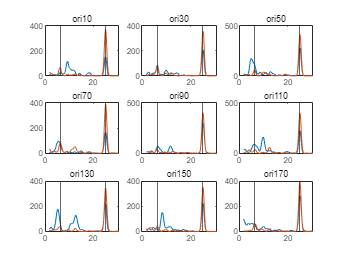

for i = 1:9
    subplot(3,3,i);
    plot(F_ROI(30:500),mean(all{i+18,1}(:,30:500),1));
    hold on
    plot(F_ROI(30:500),mean(all{i+18,2}(:,30:500),1));
    xline(6.25)
    xline(25)
    subtitle(sprintf('ori%d',i*20-10))
    hold off
end